# Vector Field Viewer Design

Load Data Stack

[fileID, filePath] = uigetfile("*.tif");
stack = readFileToStack([filePath, fileID]);

Load Vector Field if available:

[VMfile, VMpath] = uigetfile("*.mat");
load([VMpath, VMfile]);

## Generate Velocity Maps from Px and Py

[velocityMap, opt] = convertVelocitiesFromPxPy(velocityMap, position_x, position_y, position_t, opt);


## Plot single Vector Field function

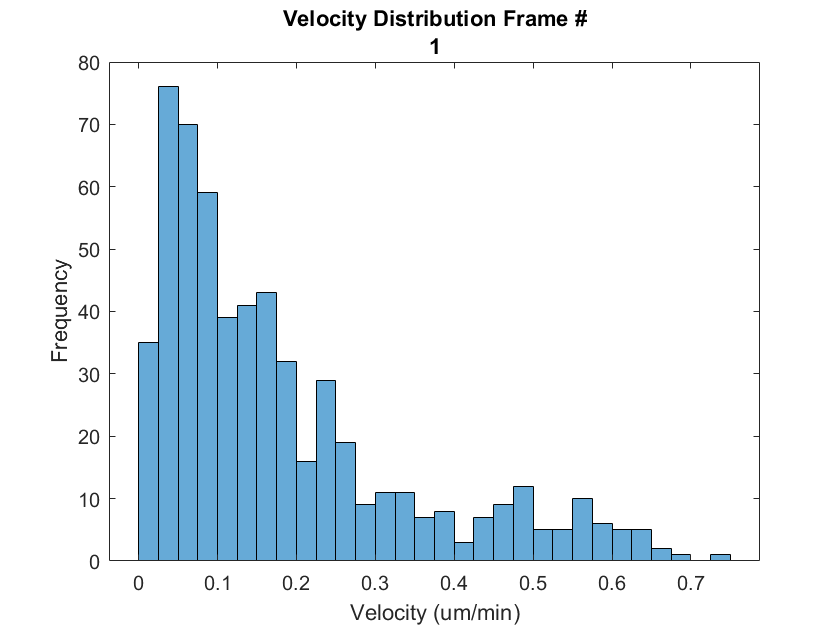

k = 1;
figure;
histogram(velocityMap{k}.VelMap, "BinWidth", 0.025);
title(["Velocity Distribution Frame #",num2str(k)]); 
xlabel("Velocity (um/min)");
ylabel("Frequency");

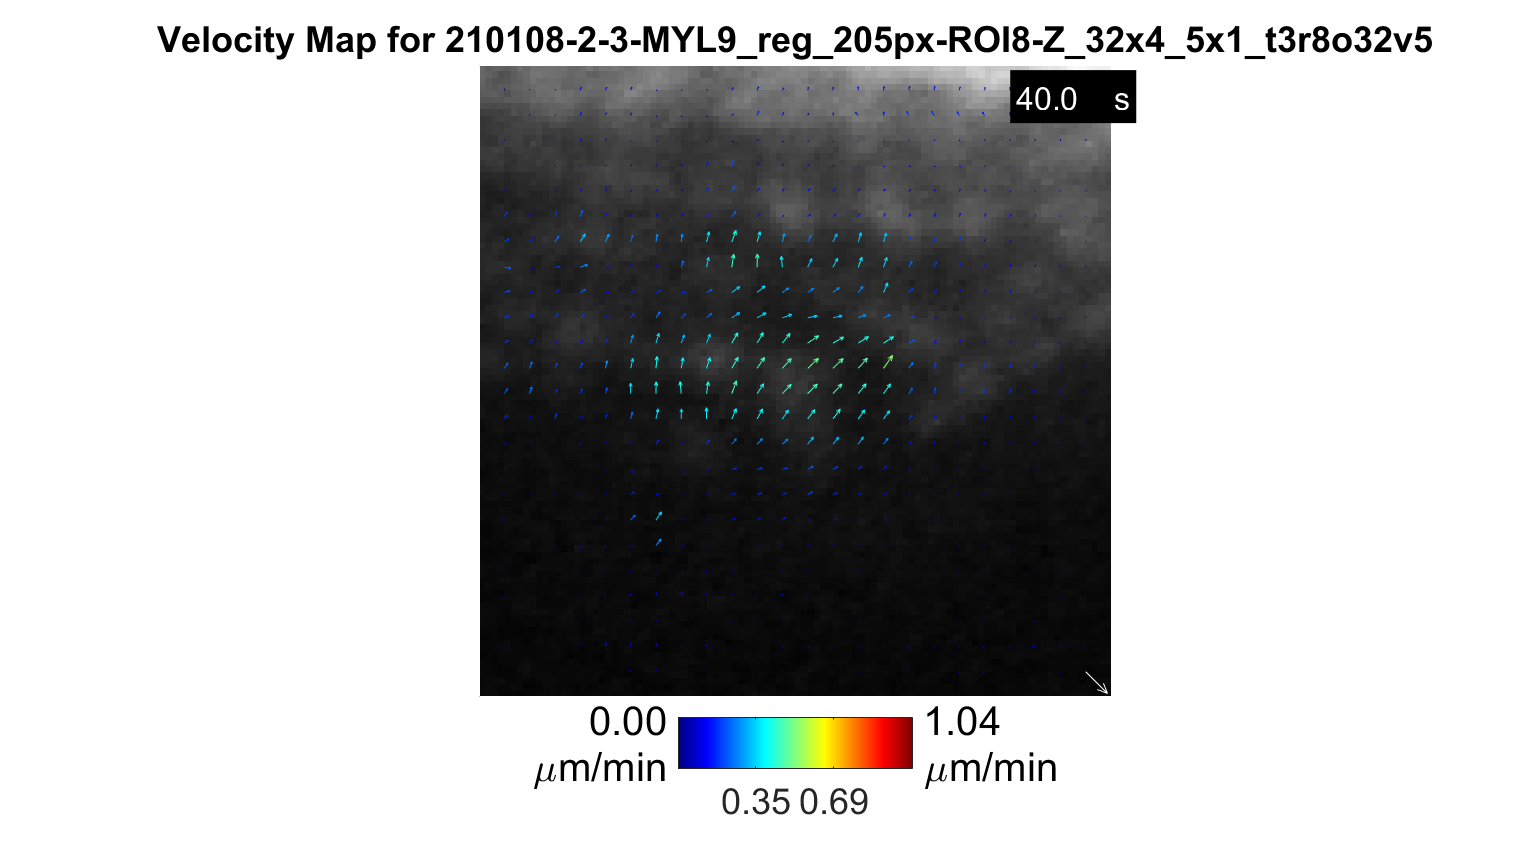

figure;


autoScale = true;
if autoScale
    opt.thresholdV = Inf;
else
    opt.thresholdV = 0.75;
end
% hold on
% figure;plot(opt.thresholdV,)

plotSingleVectorMapOnImage(velocityMap, position_t, position_x, position_y, opt, k);


% if ~isfield(opt, 'thresholdV'); opt.thresholdV = Inf;end %((opt.ROIsize*opt.pixelSize/3)/opt.timeFrame)*60;end

alltimes=unique(position_t);

correctFactor=1;%(1/0.1)*(0.06/2);

fig=figure;
    indgoodvect = find(velocityMap{1}.goodVectors);
    overallgoodvectors = indgoodvect;
    allgood = [];
for i = 1:length(velocityMap)
    posx = squeeze(position_x);
    posxall = posx(1:size(posx,1)*size(posx,2));
    posy = squeeze(position_y);
    posyall = posy(1:size(posy,1)*size(posy,2));
    
    vy = squeeze(velocityMap{i}.vy)*correctFactor;
    vyall(i,:) = vy(1:size(vy,1)*size(vy,2));
    vx = squeeze(velocityMap{i}.vx)*correctFactor;
    vxall(i,:) = vx(1:size(vx,1)*size(vx,2));
    
    %velocityMap{i}.magnitudesPerMin = sqrt(vx(velocityMap{i}.goodVectors).^2+vy(velocityMap{i}.goodVectors).^2)*60;
%     velocityMap{i}.magnitudesPerMin = sqrt(vx.^2+vy.^2)*60; % Conversion
%     done already!
velocityMap{i}.magnitudesPerMin = velocityMap{i}.VelMap;
    
    velPerMin = velocityMap{i}.magnitudesPerMin;
    magnitudesPerMin(i,:) = velPerMin(1:size(velPerMin,1)*size(velPerMin,2));
    
    % all vector that magnitudes per minutes smaller than certain thesholdV
    badVectors = find(velocityMap{i}.magnitudesPerMin>opt.thresholdV);
    toigoodvect{i} = setdiff(indgoodvect,badVectors);
    allgood = union(allgood,toigoodvect{i});
    overallgoodvectors = intersect(overallgoodvectors,toigoodvect{i});
    
    velocityMap{i}.minVel = nanmin(velocityMap{i}.magnitudesPerMin(toigoodvect{i}));
    velocityMap{i}.maxVel = nanmax(velocityMap{i}.magnitudesPerMin(toigoodvect{i}));
    allminvel(i)=velocityMap{i}.minVel;
    allmaxvel(i)=velocityMap{i}.maxVel;
  
end

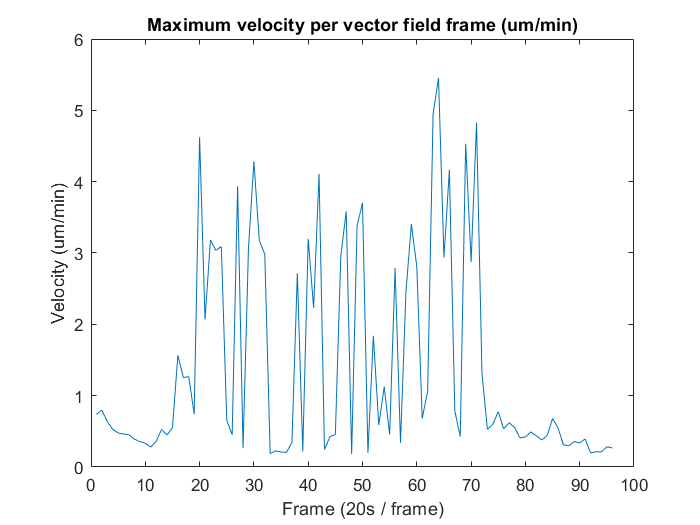

figure;
plot(allmaxvel); 
title('Maximum velocity per vector field frame (um/min)');
xlabel('Frame (20s / frame)');
ylabel('Velocity (um/min)');


minGlobalVel = nanmin(nanmin(magnitudesPerMin(:,overallgoodvectors)))

minGlobalVel = 1.6164e-18


if opt.thresholdV == Inf
    maxGlobalVel = nanmax(nanmax(magnitudesPerMin(:,overallgoodvectors)))
else
    maxGlobalVel = opt.thresholdV
end

maxGlobalVel = 5.4542